# Matrix Computations

# CPSC 5006-EL

## Assignment3

### **Haoliang Sheng 0441916**

### **Q1**

#### **3.1.5**

#### **(a)**


$$\left\lbrack \begin{array}{cc}
1 & 1\\
1 & 1\ldotp 5\\
1 & 2\\
1 & 2\ldotp 5\\
1 & 3
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_1 \\
x_2 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
1\ldotp 1\\
1\ldotp 2\\
1\ldotp 3\\
1\ldotp 3\\
1\ldotp 4
\end{array}\right\rbrack$$


#### **(b)**

t = 1:.5:3; t = t';
s = ones(5, 1); A = [s t];
y = [1.1 1.2 1.3 1.3 1.4]';
x = A \ y

x =     0.9800
    0.1400


#### **(c)**

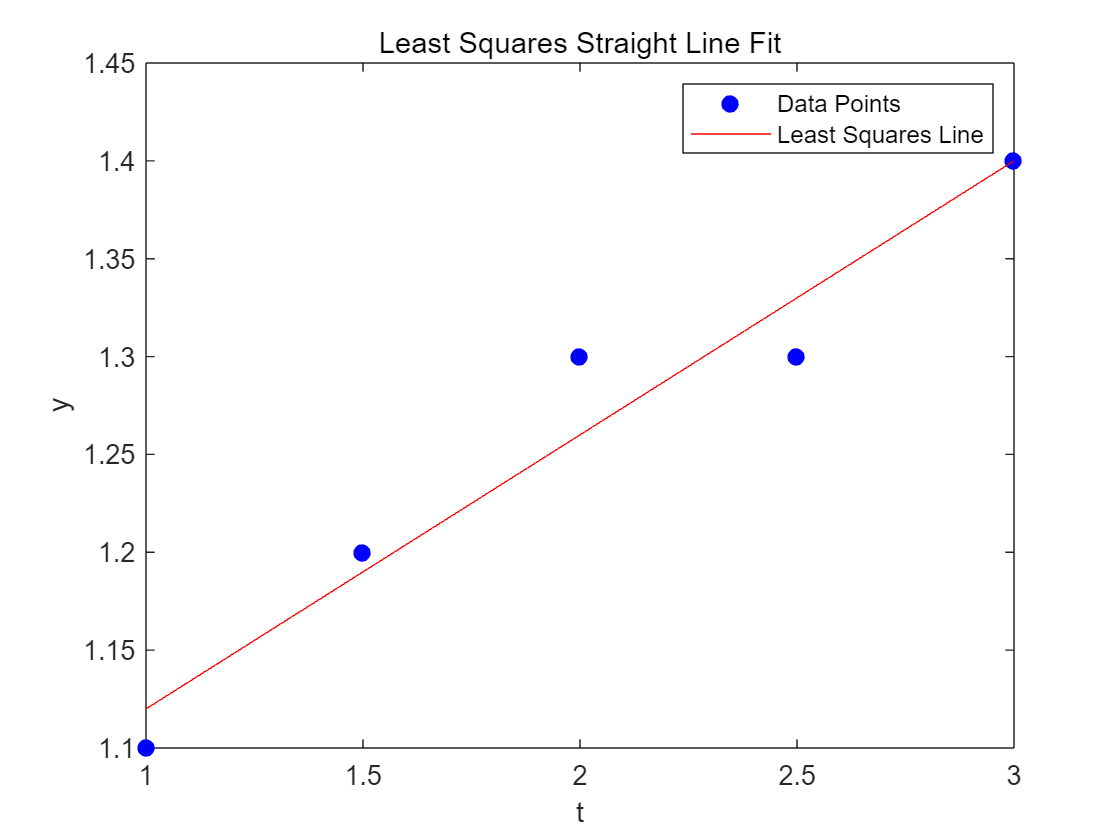

% Prepare for plotting
figure;
% Plot the data points
plot(t, y, 'bo', 'MarkerFaceColor', 'b', 'DisplayName', 'Data Points');
hold on; % Keep the plot open to add the least squares line

% Plot the least squares straight line
t_fine = linspace(min(t), max(t), 100); % finer division for line plot
y_fine = x(1) + x(2) * t_fine;
plot(t_fine, y_fine, 'r-', 'DisplayName', 'Least Squares Line');

% Set plot labels and title
xlabel('t');
ylabel('y');
title('Least Squares Straight Line Fit');

% Show legend
legend show;

% Show the plot
hold off;

#### **(d)**

norm(y - A*x)

ans = 0.0548

#### **3.1.6**

#### **(a)**


$$\left\lbrack \begin{array}{ccc}
1 & 1 & 1^2 \\
1 & 1\ldotp 5 & 1\ldotp 5^2 \\
1 & 2 & 2^2 \\
1 & 2\ldotp 5 & 2\ldotp 5^2 \\
1 & 3 & 3^2 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_1 \\
x_2 \\
x_3 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
1\ldotp 1\\
1\ldotp 2\\
1\ldotp 3\\
1\ldotp 3\\
1\ldotp 4
\end{array}\right\rbrack$$


#### **(b)**

t = 1:.5:3; t = t';
s = ones(5, 1); A = [s t power(t,2)];
y = [1.1 1.2 1.3 1.3 1.4]';
x = A \ y

x =     0.8800
    0.2543
   -0.0286


#### **(c)**

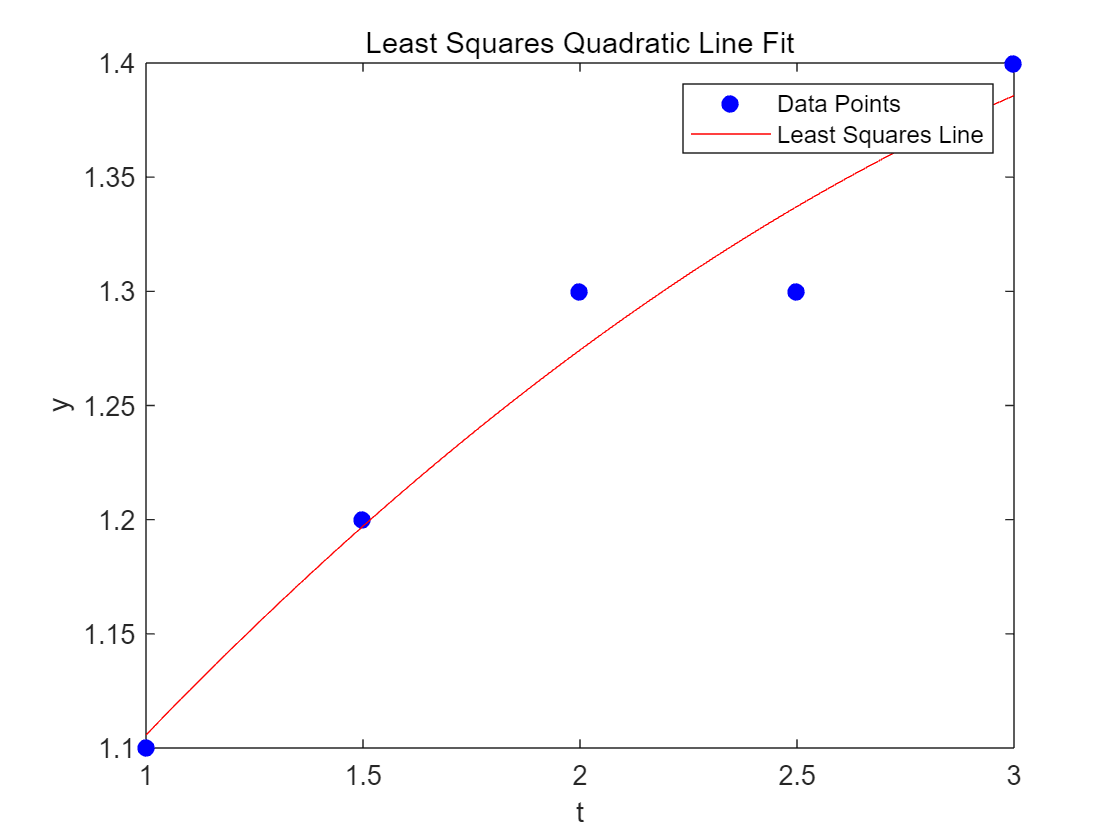

% Prepare for plotting
figure;
% Plot the data points
plot(t, y, 'bo', 'MarkerFaceColor', 'b', 'DisplayName', 'Data Points');
hold on; % Keep the plot open to add the least squares line

% Plot the least squares straight line
t_fine = linspace(min(t), max(t), 100); % finer division for line plot
y_fine = x(1) + x(2) * t_fine + x(3) * power(t_fine, 2);
plot(t_fine, y_fine, 'r-', 'DisplayName', 'Least Squares Line');

% Set plot labels and title
xlabel('t');
ylabel('y');
title('Least Squares Quadratic Line Fit');

% Show legend
legend show;

% Show the plot
hold off;

#### **(d)**

norm(y - A*x)

ans = 0.0478

### Q2

Q is orthogonal, then $QQ^T = QQ^{-1}=I
$


$$\langle Q\;x,Q\;y\rangle ={\left(Q\;y\right)}^T \left(Q\;x\right)=y^T Q^T Q\;x=y^T x=\left\langle x,y\right\rangle$$


$\langle Q\;x,Q\;x\rangle ={\left\|Q\;x\right\|}_2^2 =\left\langle x,x\right\rangle ={\left\|x\right\|}_2^2$, so ${\left\|Q\;x\right\|}_2 ={\left\|x\right\|}_2$

Since ${\left\|Q\right\|}_2 =\max_{{\left\|x\right\|}_2 =1} {\left\|Q\;x\right\|}_2$, for all x

So, ${\left\|Q\right\|}_2 =\max_{{\left\|x\right\|}_2 =1} {\left\|x\right\|}_2 =1$

Since Q is orthognal, $Q^T =Q^{-1}$also preserves vector lengths, ${\left\|Q^{-1} \right\|}_2 =1$

then $\kappa_2 \left(Q\right)={\left\|Q\right\|}_2 {\;\left\|Q^{-1} \right\|}_2 =1$

### Q3

#### 3.2.14


$$\begin{array}{l}
c=\frac{2}{\sqrt{2^2 +5^2 }}=\frac{2}{\sqrt{29\;}}\\
s=\frac{5}{\sqrt{29}}\\
Q=\left\lbrack \begin{array}{cc}
c & -s\\
s & c
\end{array}\right\rbrack =\frac{1}{\sqrt{29}}\left\lbrack \begin{array}{cc}
2 & -5\\
5 & 2
\end{array}\right\rbrack \\
R=Q^T A=\frac{1}{\sqrt{29}}\left\lbrack \begin{array}{cc}
2 & 5\\
-5 & 2
\end{array}\right\rbrack \left\lbrack \begin{array}{cc}
2 & 3\\
5 & 7
\end{array}\right\rbrack =\frac{1}{\sqrt{29}}\left\lbrack \begin{array}{cc}
29 & 41\\
0 & -1
\end{array}\right\rbrack \\
\mathrm{solving}\;Q\;c=b\\
c=Q^T b=\frac{1}{\sqrt{29}}\left\lbrack \begin{array}{cc}
2 & 5\\
-5 & 2
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
12\\
29
\end{array}\right\rbrack =\frac{1}{\sqrt{29}}\left\lbrack \begin{array}{c}
169\\
-2
\end{array}\right\rbrack \\
\mathrm{solving}\;R\;x=c\\
x_2 =\frac{-2}{-1}=2\\
x_1 =\frac{169-41*2}{29}=3\\
x=\left\lbrack \begin{array}{c}
3\\
2
\end{array}\right\rbrack 
\end{array}$$


#### 3.2.47

#### (a)


$$\begin{array}{l}
\tau ={\left\|y\right\|}_2 ={\left\|1^2 +1^2 \right\|}_2 =\sqrt{2\;}\\
\mathrm{Suppose},\;y=\left\lbrack \begin{array}{c}
-\tau \\
0
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
-\sqrt{2\;}\\
0
\end{array}\right\rbrack \\
u=\frac{\left(x-y\right)}{{\left\|x-y\right\|}_2 }=\frac{\left\lbrack \begin{array}{c}
1\\
1
\end{array}\right\rbrack -\left\lbrack \begin{array}{c}
-\sqrt{2}\\
0
\end{array}\right\rbrack }{\left\|\left\lbrack \begin{array}{c}
1\\
1
\end{array}\right\rbrack -\left\lbrack \begin{array}{c}
-\sqrt{2}\\
0
\end{array}\right\rbrack \right\|}=\frac{\left\lbrack \begin{array}{c}
1+\sqrt{2}\\
1
\end{array}\right\rbrack }{\sqrt{{\left(1+\sqrt{2}\right)}^2 +1}}=\frac{1}{\sqrt{4+2\sqrt{2}}}\left\lbrack \begin{array}{c}
1+\sqrt{2}\\
1
\end{array}\right\rbrack \\
\hat{Q} =I-2{u\;u}^T =\left\lbrack \begin{array}{cc}
1 & 0\\
0 & 1
\end{array}\right\rbrack -2{\left(\frac{1}{\sqrt{4+2\sqrt{2}}}\right)}^2 \left\lbrack \begin{array}{c}
1+\sqrt{2}\\
1
\end{array}\right\rbrack \left\lbrack \begin{array}{cc}
1+\sqrt{2} & 1
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
1 & 0\\
0 & 1
\end{array}\right\rbrack -\frac{1}{2+\sqrt{2}}\left\lbrack \begin{array}{cc}
3+2\sqrt{2} & 1+\sqrt{2}\\
1+\sqrt{2} & 1
\end{array}\right\rbrack \\
=\left\lbrack \begin{array}{cc}
1 & 0\\
0 & 1
\end{array}\right\rbrack -\left\lbrack \begin{array}{cc}
\frac{\left(3+2\sqrt{2}\right)\left(2-\sqrt{2}\right)}{2} & \frac{\left(1+\sqrt{2}\right)\left(2-\sqrt{2}\right)}{2}\\
\frac{\left(1+\sqrt{2}\right)\left(2-\sqrt{2}\right)}{2} & \frac{2-\sqrt{2}}{2}
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
1 & 0\\
0 & 1
\end{array}\right\rbrack -\left\lbrack \begin{array}{cc}
\frac{2+\sqrt{2}}{2} & \frac{\sqrt{2}}{2}\\
\frac{\sqrt{2}}{2} & \frac{2-\sqrt{2}}{2}
\end{array}\right\rbrack \\
=\left\lbrack \begin{array}{cc}
-\frac{\sqrt{2}}{2} & -\frac{\sqrt{2}}{2}\\
-\frac{\sqrt{2}}{2} & \frac{\sqrt{2}}{2}
\end{array}\right\rbrack =\frac{1}{\sqrt{2}}\left\lbrack \begin{array}{cc}
-1 & -1\\
-1 & 1
\end{array}\right\rbrack \\
\hat{R} ={\hat{Q} }^T A=\frac{1}{\sqrt{2}}\left\lbrack \begin{array}{cc}
-1 & -1\\
-1 & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{cc}
1 & 2\\
1 & 3
\end{array}\right\rbrack =\frac{1}{\sqrt{2}}\left\lbrack \begin{array}{cc}
-2 & -5\\
0 & 1
\end{array}\right\rbrack 
\end{array}$$


#### (b)


$$\begin{array}{l}
D=\left\lbrack \begin{array}{cc}
-1 & 0\\
0 & 1
\end{array}\right\rbrack \\
Q=\hat{Q} D=\frac{1}{\sqrt{2}}\left\lbrack \begin{array}{cc}
-1 & -1\\
-1 & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{cc}
-1 & 0\\
0 & 1
\end{array}\right\rbrack =\frac{1}{\sqrt{2}}\left\lbrack \begin{array}{cc}
1 & -1\\
1 & 1
\end{array}\right\rbrack \\
R=D\hat{R} =\left\lbrack \begin{array}{cc}
-1 & 0\\
0 & 1
\end{array}\right\rbrack \frac{1}{\sqrt{2}}\left\lbrack \begin{array}{cc}
-2 & -5\\
0 & 1
\end{array}\right\rbrack =\frac{1}{\sqrt{2}}\left\lbrack \begin{array}{cc}
2 & 5\\
0 & 1
\end{array}\right\rbrack 
\end{array}$$


### Q4

#### 3.2.37

#### (a)


$$u\;v^T =\left\lbrack \begin{array}{c}
u_1 \\
u_2 \\
\vdots \\
u_n 
\end{array}\right\rbrack \left\lbrack \begin{array}{cccc}
v_1  & v_2  & \cdots  & v_n 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cccc}
u_1 v_1  & u_1 v_2  & \cdots  & u_1 v_2 \\
u_2 v_1  & u_2 v_2  & \cdots  & u_2 v_n \\
\vdots  & \vdots  & \ddots  & \vdots \\
u_n v_1  & u_n v_2  & \cdots  & u_n v_n 
\end{array}\right\rbrack$$


The outer product like $u\;v^T$ results in nxn matrix.


$$\left(u\;v^T \right)B=\left\lbrack \begin{array}{cccc}
u_1 v_1  & u_1 v_2  & \cdots  & u_1 v_n \\
u_2 v_1  & u_2 v_2  & \cdots  & u_2 v_n \\
\vdots  & \vdots  & \ddots  & \vdots \\
u_n v_1  & u_n v_2  & \cdots  & u_n v_n 
\end{array}\right\rbrack \left\lbrack \begin{array}{cccc}
B_{11}  & B_{12}  & \cdots  & B_{1m} \\
B_{21}  & B_{22}  & \cdots  & B_{1m} \\
\vdots  & \vdots  & \ddots  & \vdots \\
B_{\textrm{n1}}  & B_{\textrm{n2}}  & \cdots  & B_{\textrm{nm}} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cccc}
\sum_{i=1}^n u_1 v_i B_{\textrm{i1}}  & \sum_{i=1}^n u_1 v_i B_{\textrm{i2}}  & \cdots  & \sum_{i=1}^n u_1 v_i B_{\textrm{im}} \\
\sum_{i=1}^n u_2 v_i B_{\textrm{i1}}  & \sum_{i=1}^n u_2 v_i B_{\textrm{i2}}  & \cdots  & \sum_{i=1}^n u_2 v_i B_{\textrm{im}} \\
\vdots  & \vdots  & \ddots  & \vdots \\
\sum_{i=1}^n u_n v_i B_{\textrm{i1}}  & \sum_{i=1}^n u_n v_i B_{\textrm{i2}}  & \cdots  & \sum_{i=1}^n u_n v_i B_{\textrm{im}} 
\end{array}\right\rbrack$$


`Computing uvT`

`for i from 1 to n:`

`    for j from 1 to n:`

`        uvT[i, j] = u[i] * v[j]`

`Computing (uvT)B`

`for i from 1 to n:`

`    for j from 1 to m:`

`        C[i, j] = 0`

`        for k from 1 to n:`

`            C[i, j] = C[i, j] + uvT[i, k] * B[k, j]`


$$\textrm{flops}=\sum_{i=1}^n \sum_{j=1}^n 1+\sum_{i=1}^n \sum_{j=1}^m \sum_{k=1}^n 2=n^2 +2n^2 m\approx 2n^2 m$$


#### (b)


$$v^T B=\left\lbrack \begin{array}{cccc}
v_1  & v_2  & \cdots  & v_n 
\end{array}\right\rbrack \left\lbrack \begin{array}{cccc}
B_{11}  & B_{12}  & \cdots  & B_{1m} \\
B_{21}  & B_{22}  & \cdots  & B_{1m} \\
\vdots  & \vdots  & \ddots  & \vdots \\
B_{\textrm{n1}}  & B_{\textrm{n2}}  & \cdots  & B_{\textrm{nm}} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cccc}
\sum_{i=1}^n v_i B_{\textrm{i1}}  & \sum_{i=1}^n v_i B_{\textrm{i2}}  & \cdots  & \sum_{i=1}^n v_i B_{\textrm{im}} 
\end{array}\right\rbrack$$


The product like $v^T B$ results in 1xm matrix.


$$u\left(v^T B\right)=\left\lbrack \begin{array}{c}
u_1 \\
u_2 \\
\vdots \\
u_n 
\end{array}\right\rbrack \left\lbrack \begin{array}{cccc}
\sum_{i=1}^n v_i B_{\mathrm{i1}}  & \sum_{i=1}^n v_i B_{\mathrm{i2}}  & \cdots  & \sum_{i=1}^n v_i B_{\mathrm{im}} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cccc}
u_1 \sum_{i=1}^n v_i B_{\mathrm{i1}}  & u_1 \sum_{i=1}^n v_i B_{\mathrm{i2}}  & \cdots  & u_1 \sum_{i=1}^n v_i B_{\mathrm{im}} \\
u_2 \sum_{i=1}^n v_i B_{\mathrm{i1}}  & u_2 \sum_{i=1}^n v_i B_{\mathrm{i2}}  & \cdots  & u_2 \sum_{i=1}^n v_i B_{\mathrm{im}} \\
\vdots  & \vdots  & \ddots  & \vdots \\
u_n \sum_{i=1}^n v_i B_{\mathrm{i1}}  & u_n \sum_{i=1}^n v_i B_{\mathrm{i2}}  & \cdots  & u_n \sum_{i=1}^n v_i B_{\mathrm{im}} 
\end{array}\right\rbrack$$


`Computing v^T B`

`for j from 1 to m:`

`    vTB[j] = 0`

`    for i from 1 to n:`

`        vTB[j] = vTB[j] + v[i] * B[i, j]`

`Computing u(vTB)`

`for i from 1 to n:`

`    for j from 1 to m:`

`        C[i, j] = u[i] * vTB[j]`


$$\mathrm{flops}=\sum_{j=1}^m \sum_{i=1}^n 2+\sum_{i=1}^n \sum_{j=1}^m 1=2\mathrm{nm}+\mathrm{nm}=3\mathrm{nm}$$


#### (c)


$$Q\;B=B-{u\;v}^T B=B-u\left(v^T B\right)$$


We know that $u\left(v^T B\right)$ needs 3nm flops. The minus operator takes 1nm flops

So the total flops =3nm + 1nm = 4nm

#### (d)


$$QB=\left\lbrack \begin{array}{cccc}
q_{11}  & q_{12}  & \cdots  & q_{1n} \\
q_{21}  & q_{22}  & \cdots  & q_{2n} \\
\vdots  & \vdots  & \ddots  & \vdots \\
q_{\textrm{n1}}  & q_{\textrm{n2}}  & \cdots  & q_{\textrm{nn}} 
\end{array}\right\rbrack \left\lbrack \begin{array}{cccc}
B_{11}  & B_{12}  & \cdots  & B_{1m} \\
B_{21}  & B_{22}  & \cdots  & B_{1m} \\
\vdots  & \vdots  & \ddots  & \vdots \\
B_{\textrm{n1}}  & B_{\textrm{n2}}  & \cdots  & B_{\textrm{nm}} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cccc}
\sum_{i=1}^n q_{1i} B_{\textrm{i1}}  & \sum_{i=1}^n q_{1i} B_{\textrm{i2}}  & \cdots  & \sum_{i=1}^n q_{1i} B_{\textrm{im}} \\
\sum_{i=1}^n q_{2i} B_{\textrm{i1}}  & \sum_{i=1}^n q_{2i} B_{\textrm{i2}}  & \cdots  & \sum_{i=1}^n q_{2i} B_{\textrm{im}} \\
\vdots  & \vdots  & \ddots  & \vdots \\
\sum_{i=1}^n q_{\textrm{ni}} B_{\textrm{i1}}  & \sum_{i=1}^n q_{\textrm{ni}} B_{\textrm{i2}}  & \cdots  & \sum_{i=1}^n q_{\textrm{ni}} B_{\textrm{im}} 
\end{array}\right\rbrack$$


`Computing QB`

`for i from 1 to n:`

`    for j from 1 to m:`

`        C[i, j] = 0`

`        for k from 1 to n:`

`            C[i, j] = C[i, j] + q[i, k] * B[k, j]`


$$\mathrm{flops}=\sum_{i=1}^n \sum_{j=1}^m \sum_{k=1}^n 2=2n^2 m$$


### Q5


$$Q=Q_1 Q_2 \cdots Q_{n-1}$$



$$Q_i =\left\lbrack \begin{array}{cc}
I_{i-1}  & 0\\
0 & I-\gamma_i u^{\left(i\right)} u^{\left(i\right)T} 
\end{array}\right\rbrack$$


where $I_{i-1}$ denotes the identity matrix of dimension $i-1$.

According to Q4(c), 

if $\left(Q_2 Q_3 \cdots Q_{n-1} \right)$ is computed, $Q_1 \left(Q_2 Q_3 \cdots Q_{n-1} \right)$ takes $4n^2$ flops

if $\left(Q_3 Q_4 \cdots Q_{n-1} \right)$ is computed, $Q_2 \left(Q_3 Q_4 \cdots Q_{n-1} \right)$ takes $4{\left(n-1\right)}^2$ flops

...

$Q_{n-1}$ is computed

So, computing Q takes:

$\mathrm{flops}=4n^2 +4{\left(n-1\right)}^2 +\cdots +1\approx \frac{4}{3}n^3$.

### Q6


$$Q_i =\left\lbrack \begin{array}{cc}
I_{i-1}  & 0\\
0 & I-\gamma_i u^{\left(i\right)} u^{\left(i\right)T} 
\end{array}\right\rbrack$$


where $I_{i-1}$ denotes the identity matrix of dimension $i-1$.

for k = 1, ..., n-1

    Determine $Q_k =I-\gamma_k u^{\left(k\right)} u^{\left(k\right)T}$

    
$$a_{k:n,\;k+1:n} \gets Q_k \;a_{k:n,\;k+1:n}$$


    
$$a_{\mathrm{kk}} \gets -\tau_k$$


Computing $a_{k:n,\;k+1:n} \gets Q_k \;a_{k:n,\;k+1:n}$ costs a lot more than computing $u^{\left(k\right)}$.

So $\mathrm{flops}\approx \mathrm{Compute}\;a_{k:n,\;k+1:n} \gets Q_k \;a_{k:n,\;k+1:n}$

Since $Q_k \;a_{k:n,\;k+1:n} =\left(I-\gamma_k u^{\left(k\right)} u^{\left(k\right)T} \right)a_{k:n,\;k+1:n}$

According to Q4(c), it takes $4{\left(n-k-1\right)}^2$ flops, k=1,...,n

So, $\textrm{flops}=4n^2 +4{\left(n-1\right)}^2 +\cdots +1\approx \frac{4}{3}n^3$.

### Q7

#### 3.2.39

#### (a)


$$\begin{array}{l}
\tau ={\left\|y\right\|}_2 =\sqrt{3^2 +4^2 +1^2 +3^2 +1^2 }=6\\
y=\left\lbrack \begin{array}{c}
-6\\
0\\
0\\
0\\
0
\end{array}\right\rbrack ,\;u=x-y=\left\lbrack \begin{array}{c}
3\\
4\\
1\\
3\\
1
\end{array}\right\rbrack -\left\lbrack \begin{array}{c}
-6\\
0\\
0\\
0\\
0
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
9\\
4\\
1\\
3\\
1
\end{array}\right\rbrack \\
\gamma =\frac{2}{{\left\|u\right\|}_2^2 }=\frac{2}{9^2 +4^2 +1^2 +3^2 +1^2 }=\frac{1}{54}
\end{array}$$


(i)


$$Q=I-\gamma u\;u^T =\left\lbrack \begin{array}{ccccc}
1 &  &  &  & 0\\
 & 1 &  &  & \\
 &  & 1 &  & \\
 &  &  & 1 & \\
0 &  &  &  & 1
\end{array}\right\rbrack -\frac{1}{54}\left\lbrack \begin{array}{c}
9\\
4\\
1\\
3\\
1
\end{array}\right\rbrack \left\lbrack \begin{array}{ccccc}
9 & 4 & 1 & 3 & 1
\end{array}\right\rbrack$$


(ii)


$$\begin{array}{l}
Q=\left\lbrack \begin{array}{ccccc}
1 &  &  &  & 0\\
 & 1 &  &  & \\
 &  & 1 &  & \\
 &  &  & 1 & \\
0 &  &  &  & 1
\end{array}\right\rbrack -\frac{1}{54}\left\lbrack \begin{array}{ccccc}
81 & 36 & 9 & 27 & 9\\
36 & 16 & 4 & 12 & 4\\
9 & 4 & 1 & 3 & 1\\
27 & 12 & 3 & 9 & 3\\
9 & 4 & 1 & 3 & 1
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccccc}
1 &  &  &  & 0\\
 & 1 &  &  & \\
 &  & 1 &  & \\
 &  &  & 1 & \\
0 &  &  &  & 1
\end{array}\right\rbrack -\left\lbrack \begin{array}{ccccc}
\frac{3}{2} & \frac{2}{3} & \frac{1}{6} & \frac{1}{2} & \frac{1}{6}\\
\frac{2}{3} & \frac{8}{27} & \frac{2}{27} & \frac{2}{9} & \frac{2}{27}\\
\frac{1}{6} & \frac{2}{27} & \frac{1}{54} & \frac{1}{18} & \frac{1}{54}\\
\frac{1}{2} & \frac{2}{9} & \frac{1}{27} & \frac{1}{6} & \frac{1}{18}\\
\frac{1}{6} & \frac{2}{27} & \frac{1}{54} & \frac{1}{18} & \frac{1}{54}
\end{array}\right\rbrack \\
=\left\lbrack \begin{array}{ccccc}
-\frac{1}{2} & -\frac{2}{3} & -\frac{1}{6} & -\frac{1}{2} & -\frac{1}{6}\\
-\frac{2}{3} & \frac{19}{27} & -\frac{2}{27} & -\frac{2}{9} & -\frac{2}{27}\\
-\frac{1}{6} & -\frac{2}{27} & \frac{53}{54} & -\frac{1}{18} & -\frac{1}{54}\\
-\frac{1}{2} & -\frac{2}{9} & -\frac{1}{27} & \frac{5}{6} & -\frac{1}{18}\\
-\frac{1}{6} & -\frac{2}{27} & -\frac{1}{54} & -\frac{1}{18} & \frac{53}{54}
\end{array}\right\rbrack 
\end{array}$$


#### (b)


$$\begin{array}{l}
\tau ={\left\|y\right\|}_2 =\sqrt{0^2 +2^2 +1^2 +{\left(-1\right)}^2 +0^2 }=\sqrt{6}\\
y=\left\lbrack \begin{array}{c}
-\sqrt{6}\\
0\\
0\\
0\\
0
\end{array}\right\rbrack ,\;u=a-y=\left\lbrack \begin{array}{c}
0\\
2\\
1\\
-1\\
0
\end{array}\right\rbrack -\left\lbrack \begin{array}{c}
-\sqrt{6}\\
0\\
0\\
0\\
0
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\sqrt{6}\\
2\\
1\\
-1\\
0
\end{array}\right\rbrack \\
\gamma =\frac{2}{{\left\|u\right\|}_2^2 }=\frac{2}{6+4+1+1+0}=\frac{1}{6}
\end{array}$$


(i)


$$Q\;a=\left(I-\gamma u\;u^T \right)a=\left\lbrack \begin{array}{c}
0\\
2\\
1\\
-1\\
0
\end{array}\right\rbrack -\frac{1}{6}\left\lbrack \begin{array}{c}
\sqrt{6}\\
2\\
1\\
-1\\
0
\end{array}\right\rbrack \left(\left\lbrack \begin{array}{ccccc}
\sqrt{6} & 2 & 1 & -1 & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
0\\
2\\
1\\
-1\\
0
\end{array}\right\rbrack \right)=\left\lbrack \begin{array}{c}
0\\
2\\
1\\
-1\\
0
\end{array}\right\rbrack -\frac{1}{6}*6*\left\lbrack \begin{array}{c}
\sqrt{6}\\
2\\
1\\
-1\\
0
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
-\sqrt{6}\\
0\\
0\\
0\\
0
\end{array}\right\rbrack$$


(ii)


$$\begin{array}{l}
Q=\left\lbrack \begin{array}{ccccc}
1 &  &  &  & 0\\
 & 1 &  &  & \\
 &  & 1 &  & \\
 &  &  & 1 & \\
0 &  &  &  & 1
\end{array}\right\rbrack -\frac{1}{6}\left\lbrack \begin{array}{ccccc}
6 & 2\sqrt{6} & \sqrt{6} & -\sqrt{6} & 0\\
2\sqrt{6} & 4 & 2 & -2 & 0\\
\sqrt{6} & 2 & 1 & -1 & 0\\
-\sqrt{6} & -2 & -1 & 1 & 0\\
0 & 0 & 0 & 0 & 0
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccccc}
1 &  &  &  & 0\\
 & 1 &  &  & \\
 &  & 1 &  & \\
 &  &  & 1 & \\
0 &  &  &  & 1
\end{array}\right\rbrack -\left\lbrack \begin{array}{ccccc}
1 & \frac{\sqrt{6}}{3} & \frac{\sqrt{6}}{6} & -\frac{\sqrt{6}}{6} & 0\\
\frac{\sqrt{6}}{3} & \frac{2}{3} & \frac{1}{3} & -\frac{1}{3} & 0\\
\frac{\sqrt{6}}{6} & \frac{1}{3} & \frac{1}{6} & -\frac{1}{6} & 0\\
-\frac{\sqrt{6}}{6} & -\frac{1}{3} & -\frac{1}{6} & \frac{1}{6} & 0\\
0 & 0 & 0 & 0 & 0
\end{array}\right\rbrack \\
=\left\lbrack \begin{array}{ccccc}
0 & -\frac{\sqrt{6}}{3} & -\frac{\sqrt{6}}{6} & \frac{\sqrt{6}}{6} & 0\\
-\frac{\sqrt{6}}{3} & \frac{1}{3} & -\frac{1}{3} & \frac{1}{3} & 0\\
-\frac{\sqrt{6}}{6} & -\frac{1}{3} & \frac{5}{6} & \frac{1}{6} & 0\\
\frac{\sqrt{6}}{6} & \frac{1}{3} & \frac{1}{6} & \frac{5}{6} & 0\\
0 & 0 & 0 & 0 & 1
\end{array}\right\rbrack 
\end{array}$$



$$Q\;a=\left\lbrack \begin{array}{ccccc}
0 & -\frac{\sqrt{6}}{3} & -\frac{\sqrt{6}}{6} & \frac{\sqrt{6}}{6} & 0\\
-\frac{\sqrt{6}}{3} & \frac{1}{3} & -\frac{1}{3} & \frac{1}{3} & 0\\
-\frac{\sqrt{6}}{6} & -\frac{1}{3} & \frac{5}{6} & \frac{1}{6} & 0\\
\frac{\sqrt{6}}{6} & \frac{1}{3} & \frac{1}{6} & \frac{5}{6} & 0\\
0 & 0 & 0 & 0 & 1
\end{array}\right\rbrack \;\left\lbrack \begin{array}{c}
0\\
2\\
1\\
-1\\
0
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
-\sqrt{6}\\
0\\
0\\
0\\
0
\end{array}\right\rbrack$$


#### 3.3.7

#### (a)

I guess $x=\frac{\left(9+5\right)}{2}=7$

#### (b)


$$\begin{array}{l}
c=\frac{1}{\sqrt{2}},s=\frac{1}{\sqrt{2}}\\
Q=\frac{1}{\sqrt{2}}\left\lbrack \begin{array}{cc}
1 & -1\\
1 & 1
\end{array}\right\rbrack \\
R=Q^T A=\frac{1}{\sqrt{2}}\left\lbrack \begin{array}{cc}
1 & 1\\
-1 & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
1\\
1
\end{array}\right\rbrack =\frac{1}{\sqrt{2}}\left\lbrack \begin{array}{c}
2\\
0
\end{array}\right\rbrack \\
c=Q^T b=\frac{1}{\sqrt{2}}\left\lbrack \begin{array}{cc}
1 & 1\\
-1 & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
9\\
5
\end{array}\right\rbrack =\frac{1}{\sqrt{2}}\left\lbrack \begin{array}{c}
14\\
-4
\end{array}\right\rbrack 
\end{array}$$


So, $\hat{c} =14,\hat{R} =2,d=-4$

Since $\hat{R} x=\hat{c}$, so 2x = 14, x = 7

Since ${\left\|s\right\|}_2^2 ={\left\|\hat{c} -\hat{R} x\right\|}_2^2 +{\left\|d\right\|}_2^2$ and ${\left\|\hat{c} -\hat{R} x\right\|}_2^2 =0$

then ${\left\|s\right\|}_2 ={\left\|d\right\|}_2 =4$.

### Q8

#### 3.3.10

#### (a)

n = 6; m = 3;
A = randn(n, m)

A =    -0.0068   -1.0891   -1.4916
    1.5326    0.0326   -0.7423
   -0.7697    0.5525   -1.0616
    0.3714    1.1006    2.3505
   -0.2256    1.5442   -0.6156
    1.1174    0.0859    0.7481


[Q, R] = qr(A)

Q =    -0.0033   -0.4831   -0.3096    0.6217    0.3933    0.3600
    0.7324    0.0473   -0.4648    0.1693   -0.1742   -0.4316
   -0.3678    0.2285   -0.3728    0.3201   -0.7230    0.2198
    0.1775    0.4960    0.5578    0.6386    0.0563   -0.0174
   -0.1078    0.6799   -0.4781   -0.1212    0.5092    0.1533
    0.5340    0.0620    0.0969   -0.2446   -0.1725    0.7823


R =     2.0925   -0.1011    0.7346
         0    2.2551    1.2366
         0         0    2.8805
         0         0         0
         0         0         0
         0         0         0


Q' * Q

ans =     1.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
   -0.0000    1.0000   -0.0000    0.0000    0.0000   -0.0000
    0.0000   -0.0000    1.0000    0.0000    0.0000   -0.0000
    0.0000    0.0000    0.0000    1.0000   -0.0000         0
    0.0000    0.0000    0.0000   -0.0000    1.0000   -0.0000
    0.0000   -0.0000   -0.0000         0   -0.0000    1.0000


norm(eye(n) - Q' * Q)

ans = 1.1462e-15

norm(A - Q * R)

ans = 2.7506e-15

#### (b)

% Part (a): Prepare the Vandermonde matrix for quadratic polynomial fit
t_a = [-1, -0.75, -0.5, 0, 0.25, 0.5, 0.75]';
A_a = [ones(length(t_a), 1), t_a, t_a.^2];
y_a = [1.00, 0.8125, 0.75, 1.00, 1.3125, 1.75, 2.3125]';

% Solve for part (a)
[x_a, residual_norm_a] = solve_least_squares(A_a, y_a)

x_a =     1.0000
    1.0000
    1.0000


residual_norm_a = 4.5776e-16


% Part (b): Prepare the Vandermonde matrix for linear polynomial fit - alpha
t_b_alpha = [1000, 1050, 1060, 1080, 1110, 1130]';
A_b_alpha = [ones(length(t_b_alpha), 1) * 50, t_b_alpha - 1065];
y_b_alpha = [6010, 6153, 6421, 6399, 6726, 6701]';

% Solve for part (b) - alpha
[x_b_alpha, residual_norm_b_alpha] = solve_least_squares(A_b_alpha, y_b_alpha)

x_b_alpha =   127.2458
    5.9067


residual_norm_b_alpha = 194.1091


% Part (b): Prepare the Vandermonde matrix for linear polynomial fit - beta
t_b_beta = [1000, 1050, 1060, 1080, 1110, 1130]';
A_b_beta = [ones(length(t_b_beta), 1) * 50, t_b_beta - 1065];
y_b_beta = [9422, 9300, 9220, 9150, 9042, 8800]';

% Solve for part (b) - beta
[x_b_beta, residual_norm_b_beta] = solve_least_squares(A_b_beta, y_b_beta)

x_b_beta =   183.7139
   -4.5039


residual_norm_b_beta = 136.5382

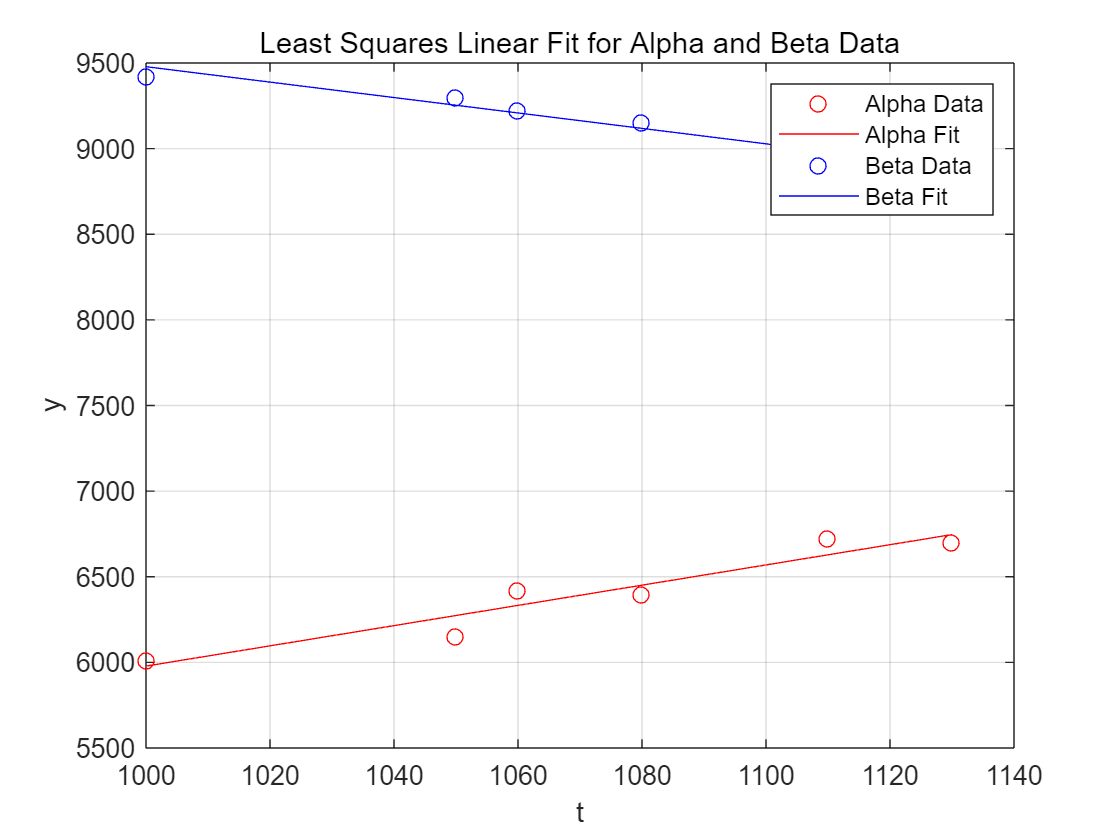


% Plotting for part (b)
figure; % Create a new figure

% Plot the data points for alpha
plot(t_b_alpha, y_b_alpha, 'ro', 'DisplayName', 'Alpha Data');
hold on; % Hold on to plot the fit on the same graph

% Compute the fitted values for alpha and plot
fitted_y_b_alpha = A_b_alpha * x_b_alpha;
plot(t_b_alpha, fitted_y_b_alpha, 'r-', 'DisplayName', 'Alpha Fit');

% Plot the data points for beta
plot(t_b_beta, y_b_beta, 'bo', 'DisplayName', 'Beta Data');

% Compute the fitted values for beta and plot
fitted_y_b_beta = A_b_beta * x_b_beta;
plot(t_b_beta, fitted_y_b_beta, 'b-', 'DisplayName', 'Beta Fit');

% Enhance the plot
title('Least Squares Linear Fit for Alpha and Beta Data');
xlabel('t');
ylabel('y');
legend('show');
grid on;
hold off; % Release the plot hold

#### 3.3.15

A = randn(5, 3)

A =    -0.1924    0.4882    0.1978
    0.8886   -0.1774    1.5877
   -0.7648   -0.1961   -0.8045
   -1.4023    1.4193    0.6966
   -1.4224    0.2916    0.8351


A = A * diag([1 3 9])

A =    -0.1924    1.4646    1.7803
    0.8886   -0.5321   14.2893
   -0.7648   -0.5882   -7.2402
   -1.4023    4.2579    6.2696
   -1.4224    0.8748    7.5158


[Q, R, P] = qr(A)

Q =    -0.0944    0.3011    0.2088   -0.8264   -0.4171
   -0.7578   -0.4255    0.1439    0.1873   -0.4347
    0.3840    0.0172   -0.4872    0.2194   -0.7529
   -0.3325    0.8522    0.0503    0.3952   -0.0675
   -0.3986    0.0433   -0.8342   -0.2788    0.2563


R =   -18.8565   -1.7252    0.0843
         0    4.3235   -1.7056
         0         0    1.5763
         0         0         0
         0         0         0


P =      0     0     1
     0     1     0
     1     0     0


diag command copy A's first column, 3 times A's second column, 9 times  A's third column.

Permutation P is $\left\lbrack \begin{array}{ccc}
 &  & 1\\
 & 1 & \\
1 &  & 
\end{array}\right\rbrack$ , it swap A's first column and third column.

A's third column has been magnified by 9, which has maximal norm.